# STATISTICAL CHARACTERISTICS OF GROUP 19 DATA WITH VISUALISATIONS

## Load the previously saved variable into MATLAB

load("ASSIGNMENT 1 STUDENT DATA VARIABLE.mat");

## Converting the structural array into tabular format

Student_Table = struct2table(Member);

## Statistaical Data

### Average age

Average_age = mean(Student_Table.Age)

Average_age = 21.8889

### Median age

median_AGE = median(Student_Table.Age)

median_AGE = 21

## Visualizations

### Histogram showing Age distribution amongst the group.

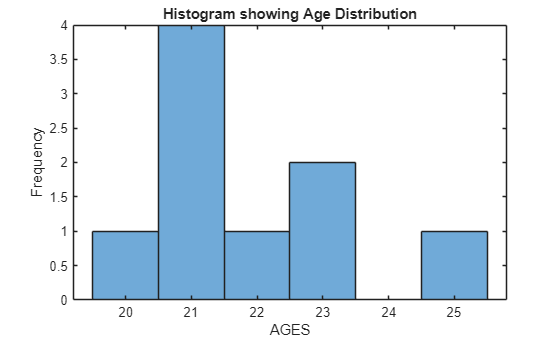

histogram(Student_Table.Age)
xlabel("AGES")
ylabel("Frequency")
title("Histogram showing Age Distribution")

### Pie chart showing Religion Distribution

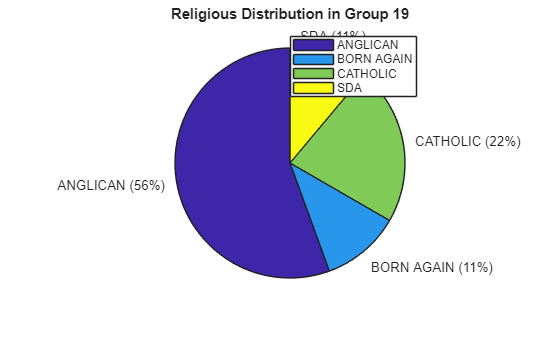

pie(categorical(Student_Table.Religion))
legend
title("Religious Distribution in Group 19")

### Horizontal Bar Chart showing Students per Course 

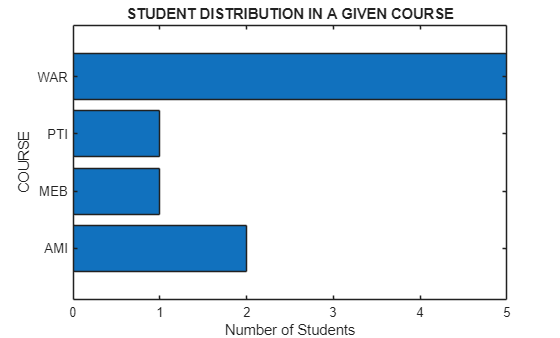

barh(categories(categorical(Student_Table.Course)), countcats(categorical(Student_Table.Course)))
xlabel("Number of Students")
ylabel("COURSE")
title("STUDENT DISTRIBUTION IN A GIVEN COURSE")

### Pareto chart showing Regional distribution of students 

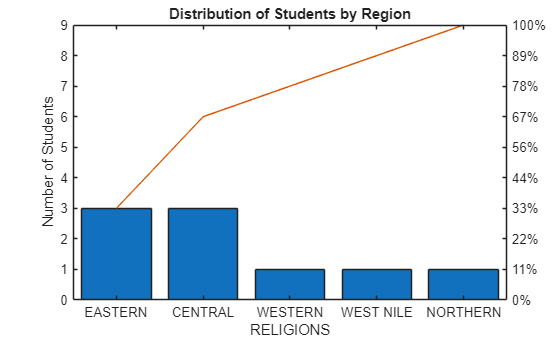

pareto(countcats(categorical(Student_Table.Region)),categories(categorical(Student_Table.Region)))
xlabel("RELIGIONS")
ylabel("Number of Students")
title("Distribution of Students by Region")

### Pie Chart showing Distribution of Gender

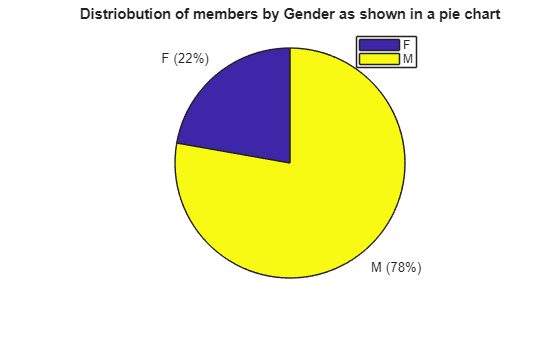

pie(categorical(Student_Table.SEX))
legend
title("Distriobution of members by Gender as shown in a pie chart")

### Heat Map showing Distribution of Students by Religion and Region

#### Constrction of Matrices for Heat map plot

Rdata = [0 1 0 0 1; 0 0 0 1 0; 0 1 0 0 0; 1 1 3 0 0];
RELIGION = ["CATHOLIC", "SDA", "BORN AGAIN", "ANGLICANS"];
REGIONS = ["NORTHERN","EASTERN","CENTRAL","WESTERN","WEST NILE"];

#### Heat Map Plot

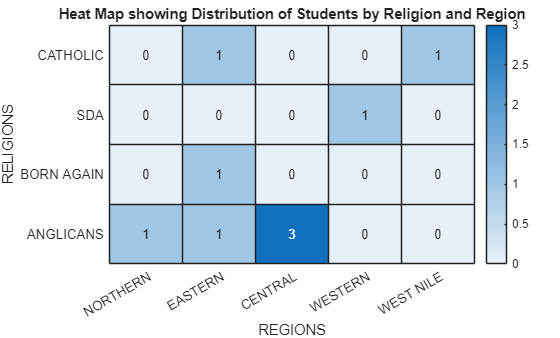

heatmap(REGIONS,RELIGION,Rdata)
xlabel("REGIONS")
ylabel("RELIGIONS")
title("Heat Map showing Distribution of Students by Religion and Region")